# F2017 - Q4 reeksamen

Opgave 1 En kontinuert stokastisk variabel X har følgende fordelingsfunktion (cdf) $F_X \left(x\right)$.

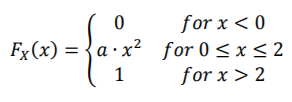

a) Bestem a, så $F_X \left(x\right)$ er en gyldig fordelingsfunktion. 

syms x a
Fx(x) = piecewise(0 > x, 0, 0 <= x <= 2, a * x^2, 2 < x, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ a\,x^{2} & \text{ if }x\in \left[0,2\right]\\ 1 & \text{ if }2<x \end{array}\right.$$

For en gyldig tæthedsfunktion $F_X \left(x\right)<1$ skal a være:

a = solve(Fx(2) == 1, a)

$$a = \frac{1}{4}$$

b) Bestem og tegn tæthedsfunktionen (pdf) $f_X \left(x\right)$ for X.�.

a = 1/4;
Fx(x) = piecewise(0 > x, 0, 2 >= x >= 0, a * x^2, 2 < x, 1);
fx(x) = diff(Fx(x))

$$fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{x}{2} & \text{ if }x\in \left(0,2\right)\\ 0 & \text{ if }2<x \end{array}\right.$$

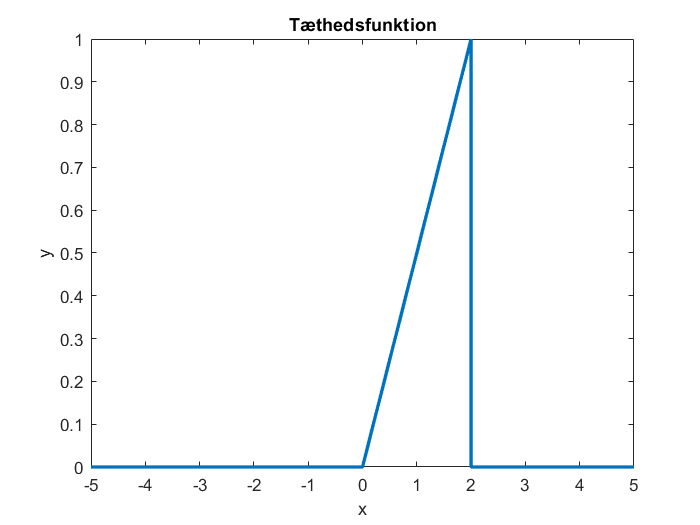

figure()
fplot(fx(x), 'linewidth',2);
title('Tæthedsfunktion');
xlabel('x');
ylabel('y');

c) Bestem sandsynligheden for 1 ≤ X ≤ 2.

PrX = (1-Fx(1)) - (1-Fx(2))

$$PrX = \frac{3}{4}$$

d) Bestem middelværdien og variansen af X.

Forventningsværdien findes ved:

EX = int(x * fx(x),'x',-Inf,Inf)

$$EX = \frac{4}{3}$$

Variansen findes ved:

varX = int(x^2*fx(x),'x',-Inf,Inf)-(EX^2)

$$varX = \frac{2}{9}$$

## Opgave 2

En leverance af modstande indeholder:

Modstandene leveres både som 5% modstande og 1% modstande. 1% modstandene udgør 1/4 af 1 kΩ, 1/2 af 10 kΩ og 3/4 af 100 kΩ modstandene. Modstandene er desværre blevet blandet sammen og leveres i én blandet pose. En modstand udtages tilfældigt fra leverancen.

`Antal af Hændelse A:`

`Antal af Hændelse B:`

`Antal af Hændelse C:`

`Samlet antal af Hændelse A+B+C:`

`Likelihood: Relative Frequency Approach`

a) Hvad er sandsynligheden for, at den udtagne modstand er hhv. en 1 kΩ, 10 kΩ eller 100 kΩ modstand?

N1k = 1000; N10k = 800; N100k = 400;
N = N1k + N10k + N100k

N = 2200

Pr1k = N1k/N

Pr1k = 0.4545

Pr10k = N10k/N

Pr10k = 0.3636

Pr100k = N100k/N

Pr100k = 0.1818

b) Hvad er sandsynligheden for, at modstanden er en 10 kΩ 1% modstand?

`Joint Events: Sandsynlighed for at trække en 10kOhms modstand og det er en 1% modstand`

Pr1p10k = 0.5;
Pr10k1p = Pr10k * Pr1p10k

Pr10k1p = 0.1818

c) Hvad er sandsynligheden for, at det er en 1% modstand uanset størrelse?

Sandsynlighed for 1kOhm 1% modstand

Pr1p1k = 0.25;
Pr1k1p = Pr1k * Pr1p1k

Pr1k1p = 0.1136

Sandsynlighed for 100kOhm 1% modstand

Pr1p100k = 0.75;
Pr100k1p = Pr100k * Pr1p100k

Pr100k1p = 0.1364

`Total Probality: Sandsynligheden for 1% modstand uanset størrelse (Sum Rule)`

PrT = Pr1k1p + Pr10k1p + Pr100k1p

PrT = 0.4318

d) Hvis den udtagne modstand er en 5% modstand, hvad er så sandsynligheden for at den er på 100 kΩ?

Sandsynlighed for en 5% modstand

PrNT = 1 - PrT

PrNT = 0.5682

Pr5p100k = 1-Pr1p100k

Pr5p100k = 0.2500

Pr100k5p = (Pr5p100k * Pr100k) / PrNT

Pr100k5p = 0.0800

## Opgave 3

En diskret stokastisk proces X(n) er givet ved:

hvor W(n) er i.i.d. fordelte efter:

a) Skitser 10 samples af én realisation af processen X(n). Dvs. for n=1, 2,…,10

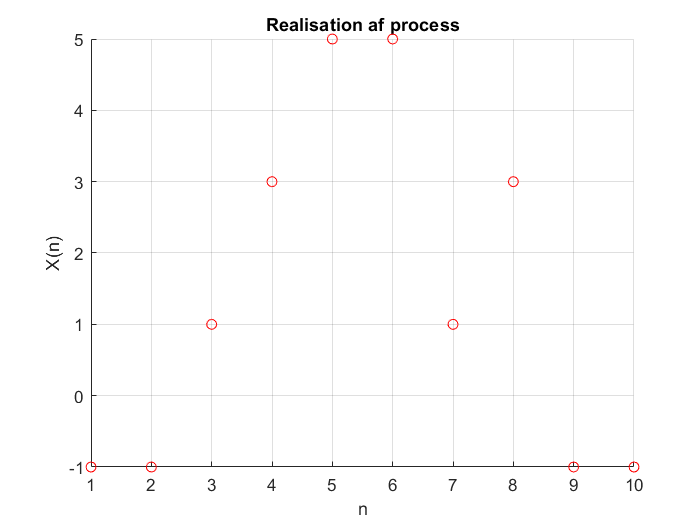

N = 10; % Antal samples
max = 4;

w = unidrnd(max, 1, N) - 1;
Xn = 2*w -1;
x = [1:1:N];
figure()
scatter(x, Xn, 'or')
grid on; 
xlabel("n"); ylabel("X(n)"); title("Realisation af process");

b) Bestem middelværdien og variansen af én realisation af X(n).

a = nedre grænse, b = øvre grænse

a = 0; b = 3;
mean_Xn = 2 * (a+b)/2 - 1

mean_Xn =        2       


Variansen af en konstant er lig 0, variansen af $a$ bliver til $a^2$ efter gældende regneregler for varians og kovarians.

var_X = 4*((((b-a+1)^2)-1)/12)

var_X =        5       


c) Bestem ensemble middelværdien og variansen for processen X(n).

format rat
ensemble_mean = (a+b)/2

ensemble_mean =        3/2     


ensemble_variance = (((b - a + 1)^2)-1) / 12

ensemble_variance =        5/4     


d) Angiv om processen er WSS (stationær i den brede forstand), og om den er ergodisk. Svarene skal begrundes.

Processen er WSS da ensemble mean ikke ændrer sig (konstant). 

Den er ergodisk da vi kan sige noget om procsessen generelt ud fra en sample. 

## Opgave 4

For en bestemt type batterier angives i specifikationen fra leverandøren, at levetiden T for batterierne er normalfordelt med en middellevetid på 3000 timer med en standard afvigelse på 100 timer: T ~ N(3000 timer; (100 timer)^2). Der udtages tilfældigt 12 batterier af pågældende type. Ved en test måles levetiden af disse til: 

a) Opstil en hypotese test for at bestemme om middellevetiden for batteritypen stemmer med leverandørens specifikation.


$$H_0 :\mu =\mu_0$$



$$H_1 :\mu \not= \mu_0$$


b) Bestem den estimerede middellevetid for batteritypen.

n = 12; sigma = sqrt(100^2);
T = [3148 2956 2803 2933 2869 3111 2789 2995 2909 2929 3148 2867];
mu_est = (1/n)*sum(T)

mu_est = 2.9548e+03

mean(T)

ans = 2.9548e+03

c) Anvend en z-test til test af din hypotese. Kan NULL-hypotesen afvises med et signifikantniveau på 0,05? Svaret skal begrundes. 

mu0 = 3000; % hypotese
z = (mu_est-mu0)/(sigma/sqrt(n)) % teststørrelse

z = -1.5675

pval = 2 * (1 - normcdf(abs(z)))'

pval = 0.1170

Hypotesen kan ikke afvises da p > 0,05.

d) Bestem 95% konfidens intervallet for batterilevetiden T.

mu_lower = mu_est - 1.96 * (sigma/sqrt(n))

mu_lower = 2.8982e+03

mu_upper = mu_est + 1.96 * (sigma/sqrt(n))

mu_upper = 3.0113e+03